# HW 2 - Matlab Exercise 2

Module 2 consists of 8 sections. loading data as we did before is where we begin

data = load('../HMP_Dataset/Climb_stairs/Accelerometer-2011-03-24-10-24-39-climb_stairs-f1.txt');
% loading in the data from the csv matrix
converted_data = convert(data);
x = converted_data(:,1);
y = converted_data(:,2);
z = converted_data(:,3);

## Combining of signal

can be done with an anon function

S = @(a, b, c) (sqrt(a.^2 + b.^2 + c.^2 ))

S = function_handle with value:
    @(a,b,c)(sqrt(a.^2+b.^2+c.^2))


with this we can convert the signal for computing the energy of it.


$$E=\int_{-\infty }^{\infty } |S|^2 \textrm{dt}$$


We are in a discrete environment, so we need the following.


$$E=\sum_{-\infty }^{\infty } |S|^2$$


matlabs sum function can do this across the vector and we can pass in the squared magnitude

E = sum(mag_sigquared)

## 2 combine and calculate energy

sig_sig = S(x, y, z)';
mag_sigquared = abs(sig_sig).^2;
energy_sig = sum(mag_sigquared,"all","omitmissing","double")

energy_sig = 2.6534e+04

The energy of S is obtained.

## 3 Implementation of moving average

showing the moving average working on the data below. this does not have names on the plots, but we can make a names vector for it and add it programatically

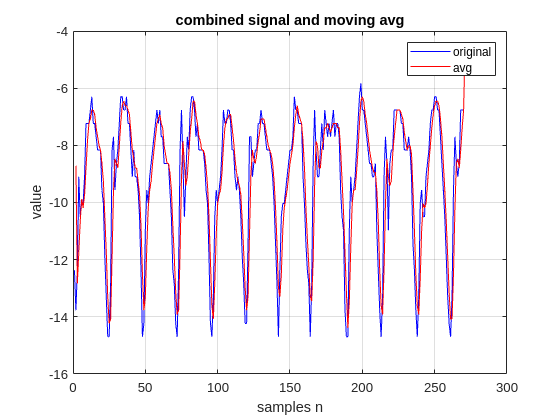

plot_avgs(x)

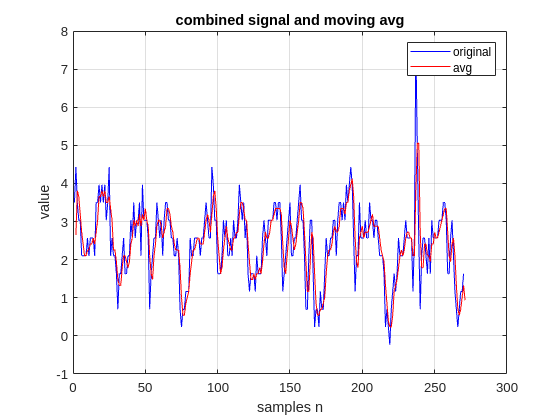

plot_avgs(y)

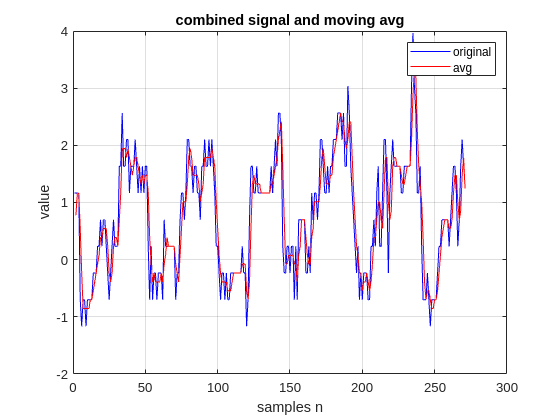

plot_avgs(z)

## get all at once with the data and converted data

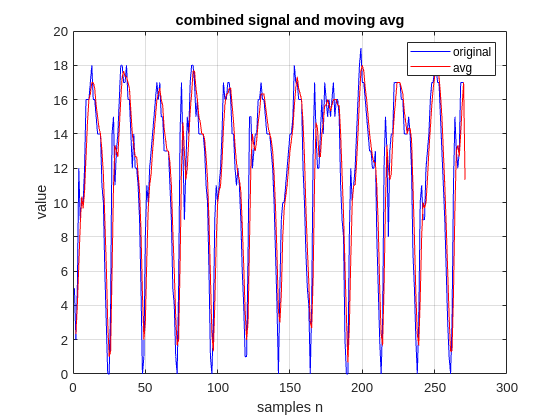

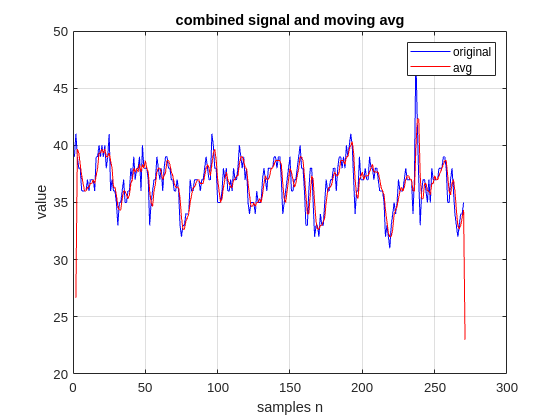

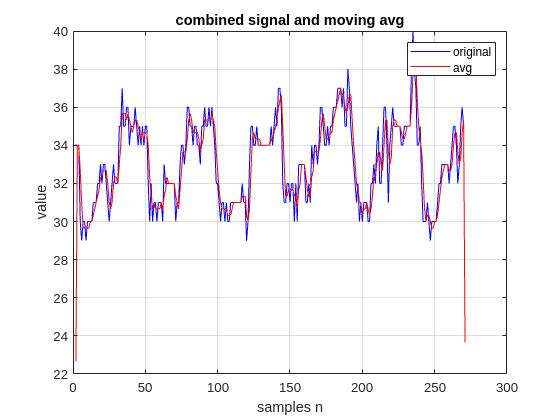

for i = 1:3
    figure
    plot_avgs(data(:,i))
    pause(.1)
    figure
    plot_avgs(converted_data(:,i))
    pause(.1)
end

## Here is the convolved impulse $\delta$ across the signals 

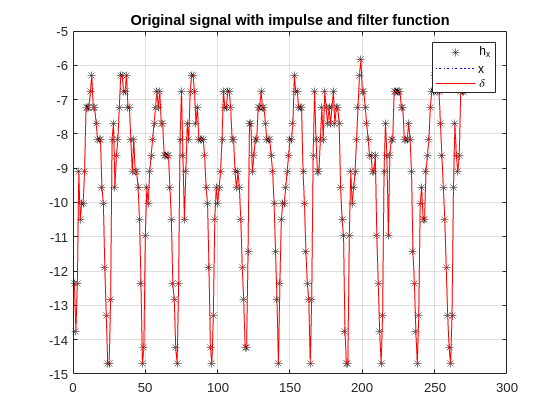

impulse = 1;
figure
conv_sig = conv(x,impulse);
hx = filter(impulse,1,x);
hy = filter(impulse,1,y);
hz = filter(impulse,1,z);
reg_range = (1:1:length(hx))';
figure()
plot(reg_range,hx,'k*',1:1:length(x),x,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with impulse and filter function')
legend("h_x","x","\delta")
grid on

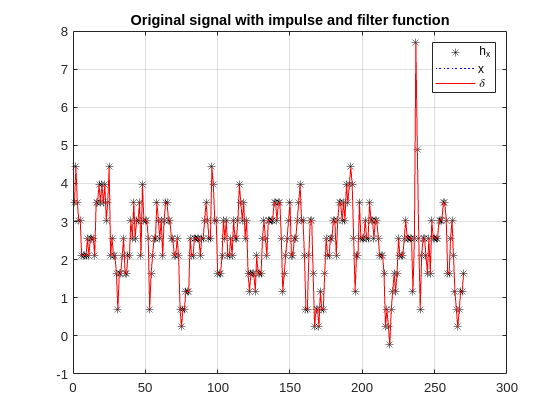


impulse = 1;
figure
conv_sig = conv(y,impulse);
reg_range = (1:1:length(hy))';
figure()
plot(reg_range,hy,'k*',1:1:length(y),y,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with impulse and filter function')
legend("h_x","x","\delta")
grid on

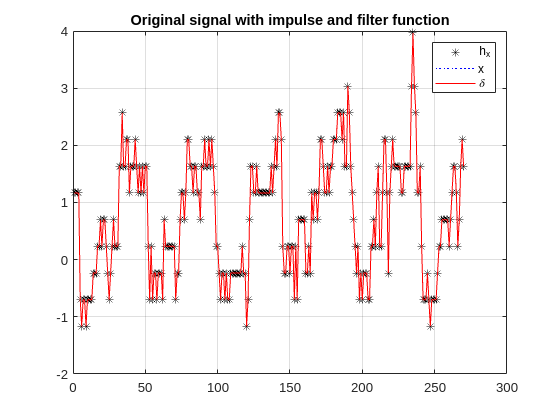


impulse = 1;
figure
conv_sig = conv(z,impulse);
reg_range = (1:1:length(hz))';
figure()
plot(reg_range,hz,'k*',1:1:length(z),z,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with impulse and filter function')
legend("h_x","x","\delta")
grid on

## 4 Recursive system 1

These are the plots of the recursive system for problem 4 

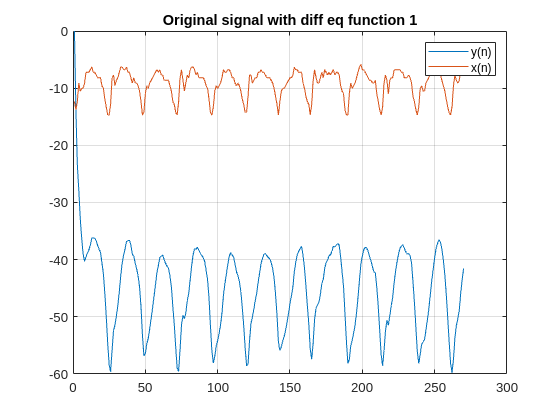

figure()
diff1_x = [diffeq_1(x),x];
plot(diff1_x)
title('Original signal with diff eq function 1')
legend("y(n)","x(n)")
grid on

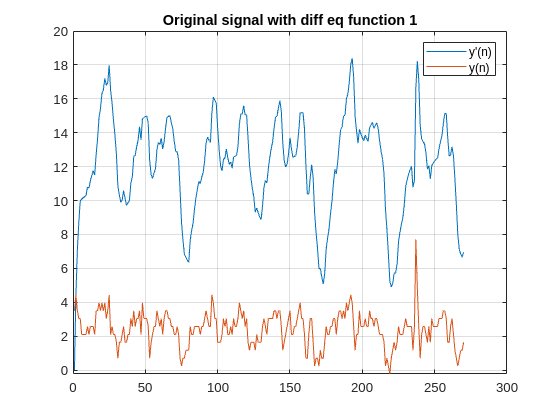


figure()
diff1_y = [diffeq_1(y),y];
plot(diff1_y)
title('Original signal with diff eq function 1')
legend("y'(n)","y(n)")
grid on

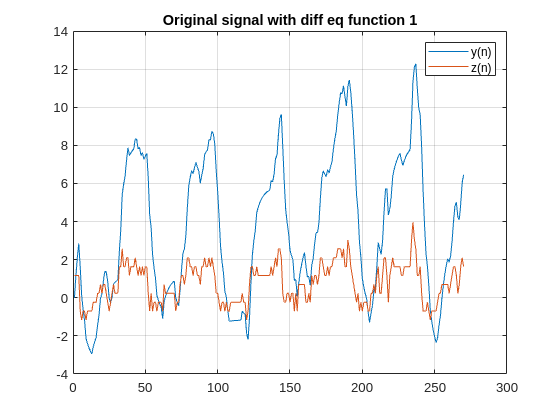


figure()
diff1_z = [diffeq_1(z),z];
plot(diff1_z)
title('Original signal with diff eq function 1')
legend("y(n)","z(n)")
grid on

## 5 Recursive system 2

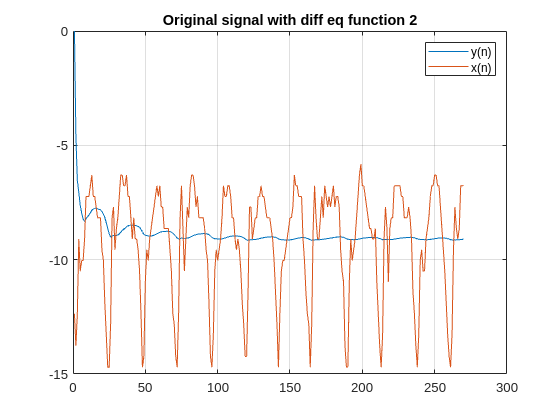

figure()
diff2_x = [diffeq_2(x),x];
plot(diff2_x)
title('Original signal with diff eq function 2')
legend("y(n)","x(n)")
grid on

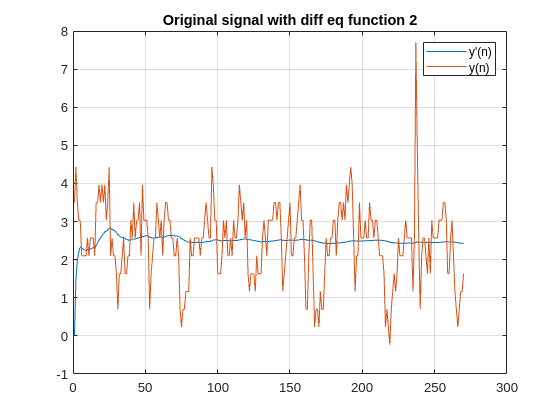


figure()
diff2_y = [diffeq_2(y),y];
plot(diff2_y)
title('Original signal with diff eq function 2')
legend("y'(n)","y(n)")
grid on

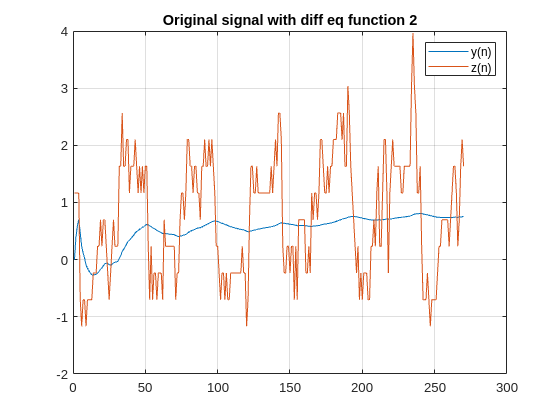


figure()
diff2_z = [diffeq_2(z),z];
plot(diff2_z)
title('Original signal with diff eq function 2')
legend("y(n)","z(n)")
grid on

This system is computing a cumulative average. I cannot remember the term mentioned in class, but we can see that the last value calculated is one thatcounts toward the sum the least overall. same effect as having an average that you add one more value to, it is by definition a single value more than the average had increased by prior to this addition. the y term being multiplied by n shows that it must be first multiplied by the total number of elements that had been included thusfar.

## 6 Recursive system 3

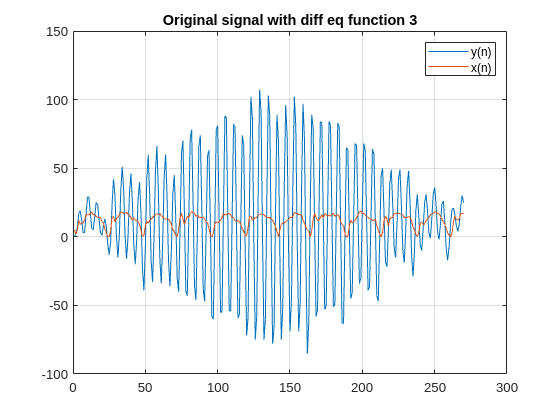

x = data(:,1);
y = data(:,2);
z = data(:,3);
figure()
diff3_x = [diffeq_3(x),x];
plot(diff3_x)
title('Original signal with diff eq function 3')
legend("y(n)","x(n)")
grid on

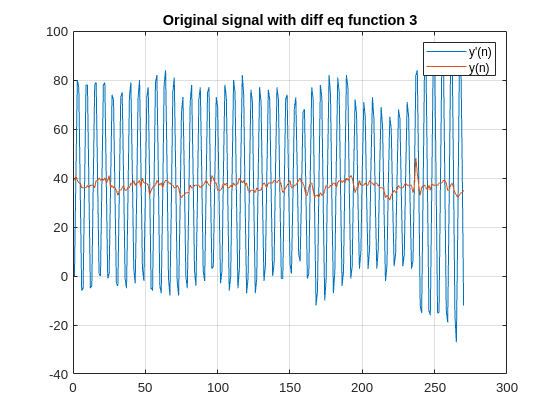


figure()
diff3_y = [diffeq_3(y),y];
plot(diff3_y)
title('Original signal with diff eq function 3')
legend("y'(n)","y(n)")
grid on

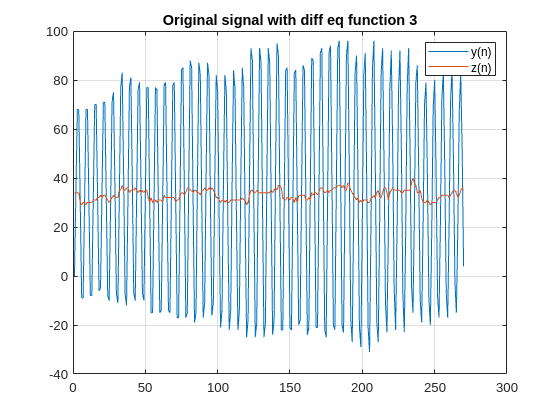


figure()
diff3_z = [diffeq_3(z),z];
plot(diff3_z)
title('Original signal with diff eq function 3')
legend("y(n)","z(n)")
grid on

I know these should be LTI systems, but I am not sure exactly if my tests prove that.

## recursive shift for system 1 on x data and converted x data to see differences and test LTI Note** none of the below was asked for, but I thought it would be cool to try a test for LTI in this way.

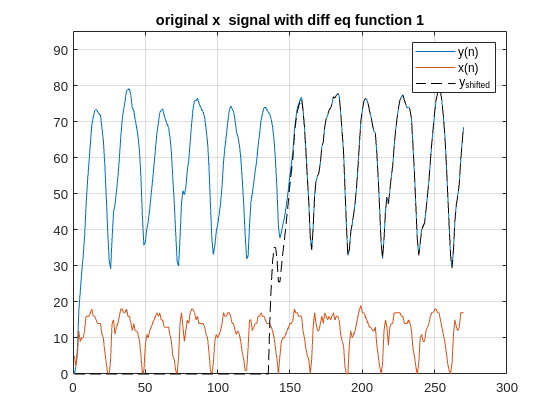

x = data(:,1);
y = data(:,2);
z = data(:,3);
figure
lti_test1(x,1,'original x ')

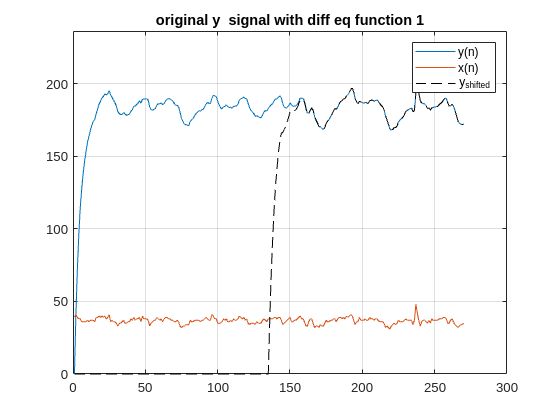

figure
lti_test1(y,1,'original y ')

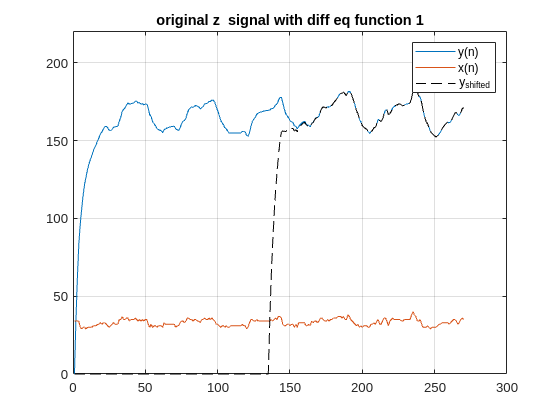

figure
lti_test1(z,1,'original z ')

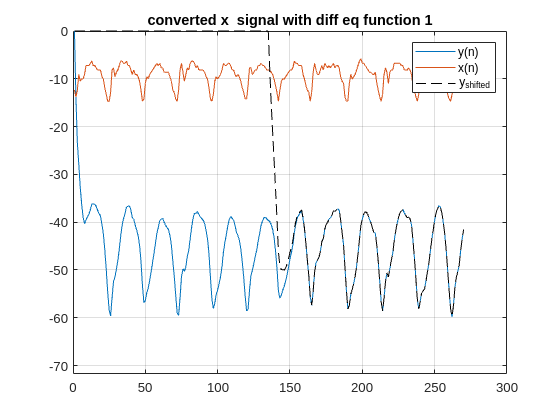


x = converted_data(:,1);
y = converted_data(:,2);
z = converted_data(:,3);

figure
lti_test1(x,1,'converted x ')

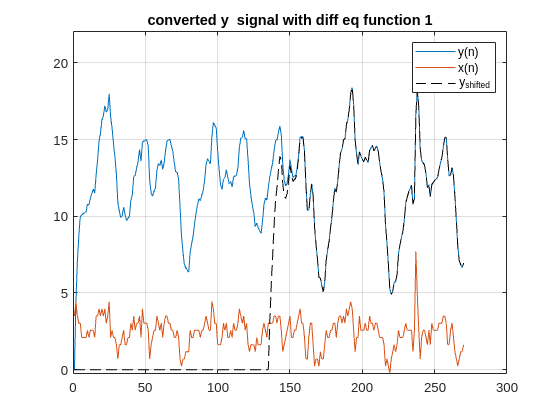

figure
lti_test1(y,1,'converted y ')

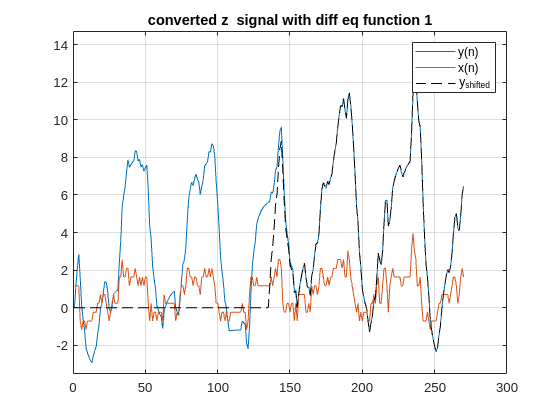

figure
lti_test1(z,1,'converted z ')

## recursive shift for system 2 on x data and converted x data to see differences and test LTI

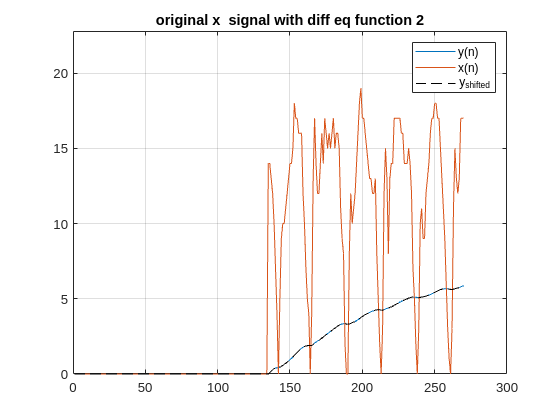

x = data(:,1);
y = data(:,2);
z = data(:,3);
figure
lti_test2(x,1,'original x ')

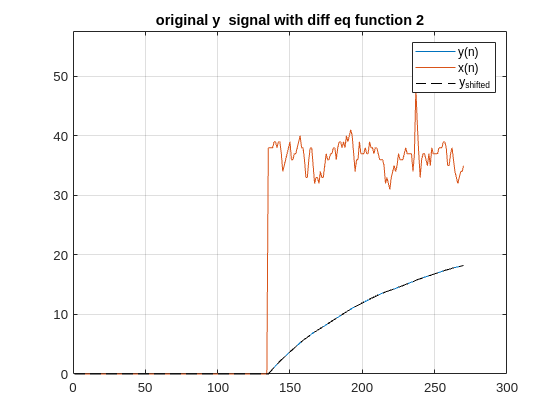

figure
lti_test2(y,1,'original y ')

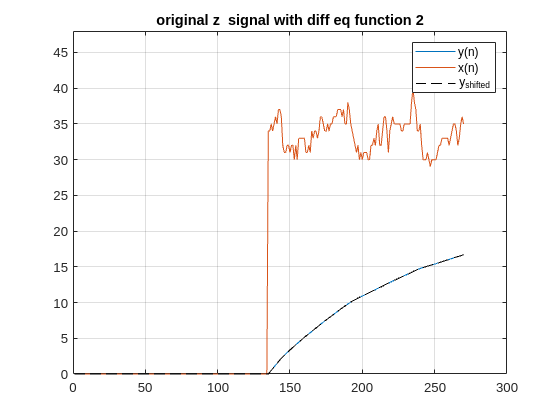

figure
lti_test2(z,1,'original z ')

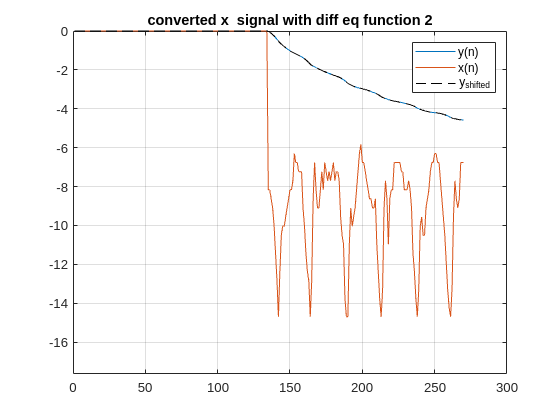


x = converted_data(:,1);
y = converted_data(:,2);
z = converted_data(:,3);

figure
lti_test2(x,1,'converted x ')

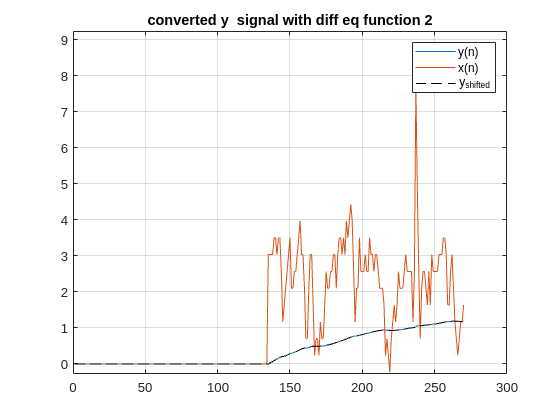

figure
lti_test2(y,1,'converted y ')

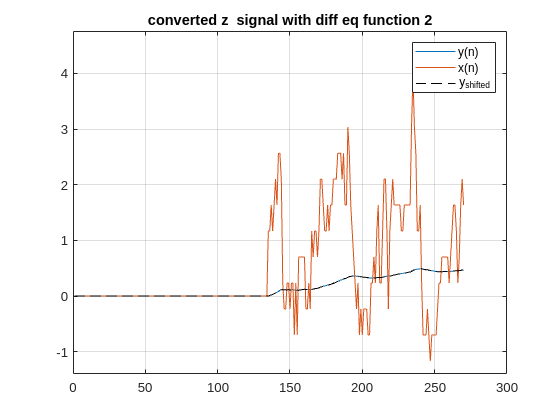

figure
lti_test2(z,1,'converted z ')

## recursive shift for system 3 on x data and converted x data to see differences and test LTI

x = data(:,1);
y = data(:,2);
z = data(:,3);
figure
lti_test3(x,1,'original x ')
figure
lti_test3(y,1,'original y ')
figure
lti_test3(z,1,'original z ')

x = converted_data(:,1);
y = converted_data(:,2);
z = converted_data(:,3);

figure
lti_test3(x,1,'converted x ')
figure
lti_test3(y,1,'converted y ')
figure
lti_test3(z,1,'converted z ')

## 7 crosscorrelations of original data

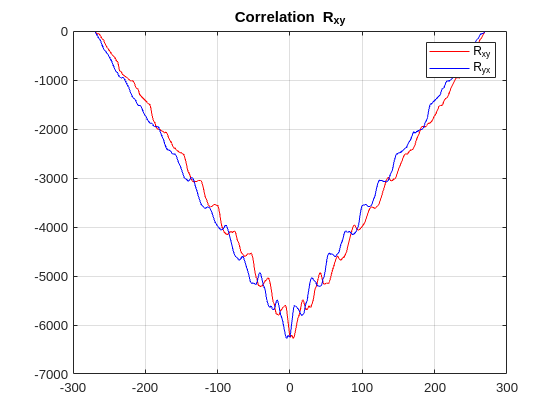

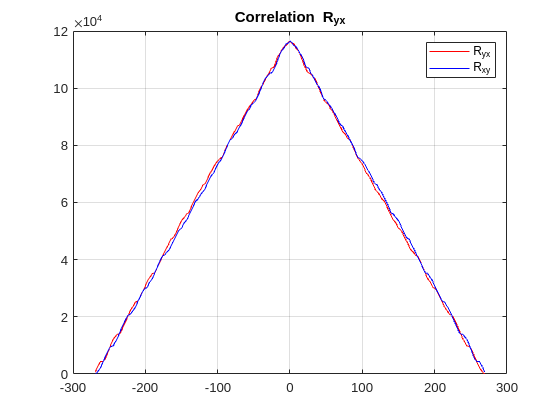

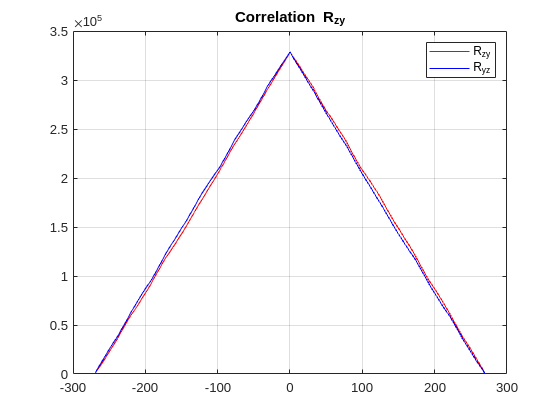

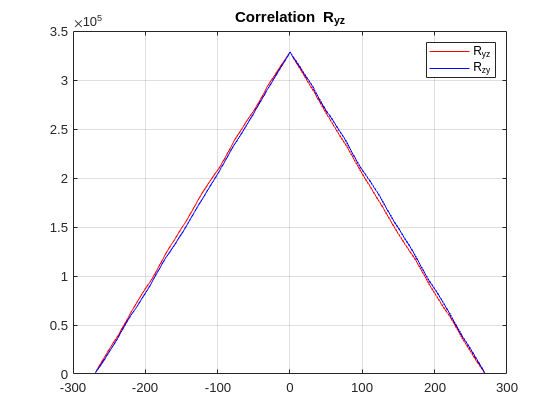

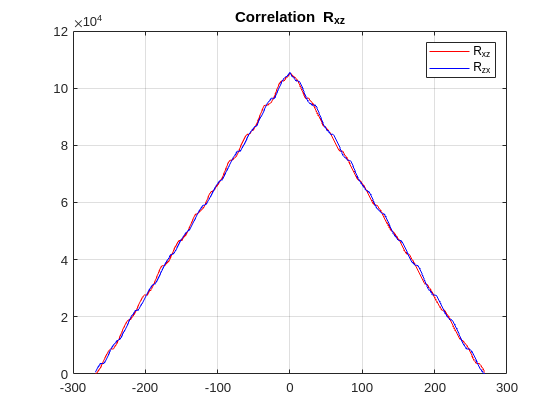

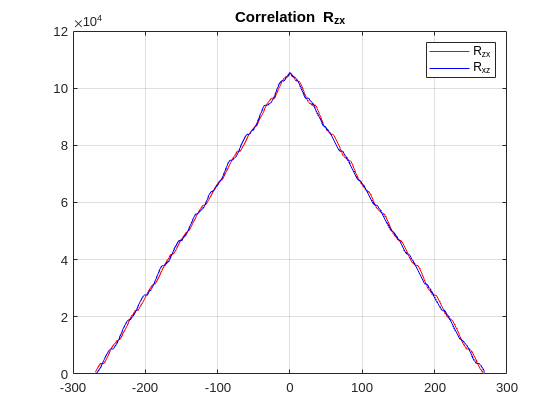

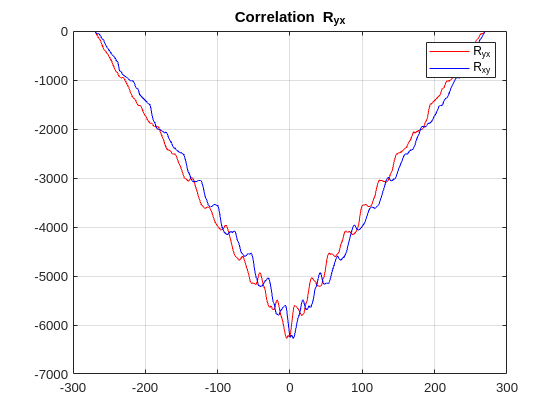

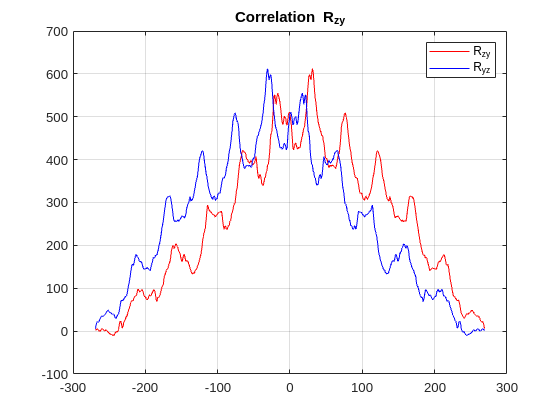


x = data(:,1);

y = data(:,2);
z = data(:,3);
cross_corr(x,y,'xy')
cross_corr(y,x,'yx')

cross_corr(z,y,'zy')
cross_corr(y,z,'yz')

cross_corr(x,z,'xz')
cross_corr(z,x,'zx')

## crosscorrelations of converted data

x = converted_data(:,1);
y = converted_data(:,2);
z = converted_data(:,3);
cross_corr(x,y,'xy')
cross_corr(y,x,'yx')

cross_corr(z,y,'zy')
cross_corr(y,z,'yz')

cross_corr(x,z,'xz')
cross_corr(z,x,'zx')

## Problem 2.65 from text parts a-d

a = [1, 1, 1, 1, 1, -1,-1, 1, 1, -1, 1, -1, 1];
variance = [.01,.1, 1];
delay = 20;
ya = zeros(1,199);
x_a = [zeros(1,delay),a,zeros(1,delay)];

a) the location between peaks in the correlation and the autocorrelation will be the total delay.

b) above as 

generation of rands and vec for part c and d. I am not sure what is going wrong here. check into it 

figure
plot(x_a)
hold on
alpha = .9;
noise = alpha.*sqrt(variance)'*randn(1,199)

noise =    -0.0106    0.0629    0.0243    0.0445   -0.1335   -0.0918   -0.0402    0.0099    0.1016   -0.0261    0.1135    0.0428    0.1057    0.0114   -0.0591   -0.1333    0.0140    0.0737   -0.0263   -0.0487   -0.0278   -0.0987   -0.0444   -0.0163    0.0041   -0.0057    0.0550    0.0098    0.1633    0.0281    0.1624   -0.0651    0.0474   -0.0234    0.0540    0.0535   -0.1967   -0.1194   -0.1297    0.0362    0.1323   -0.0294    0.0731    0.0491   -0.0946    0.0358   -0.0677    0.1365   -0.0029    0.1472
   -0.0335    0.1990    0.0767    0.1407   -0.4221   -0.2904   -0.1272    0.0312    0.3212   -0.0825    0.3590    0.1353    0.3342    0.0361   -0.1869   -0.4216    0.0443    0.2330   -0.0833   -0.1539   -0.0878   -0.3121   -0.1403   -0.0514    0.0130   -0.0182    0.1740    0.0311    0.5163    0.0888    0.5136   -0.2058    0.1499   -0.0741    0.1708    0.1690   -0.6222   -0.3777   -0.4101    0.1144    0.4184   -0.0930    0.2312    0.1553   -0.2993    0.1131   -0.2140    0.4315   -0.0093 

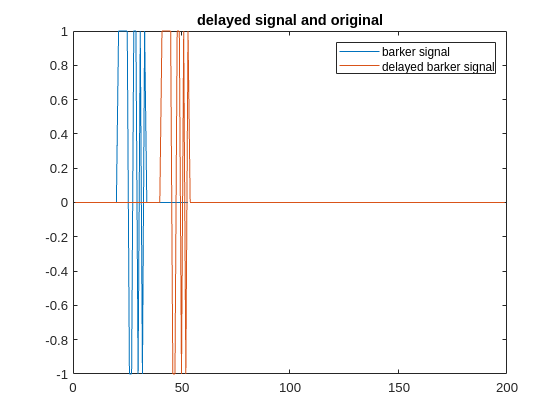

 
ya(:,delay+1:delay+length(x_a)) = x_a;
plot(ya)
title('delayed signal and original')
legend("barker signal","delayed barker signal")
hold off

ya = ya + noise(1,:)

ya =    -0.0106    0.0629    0.0243    0.0445   -0.1335   -0.0918   -0.0402    0.0099    0.1016   -0.0261    0.1135    0.0428    0.1057    0.0114   -0.0591   -0.1333    0.0140    0.0737   -0.0263   -0.0487   -0.0278   -0.0987   -0.0444   -0.0163    0.0041   -0.0057    0.0550    0.0098    0.1633    0.0281    0.1624   -0.0651    0.0474   -0.0234    0.0540    0.0535   -0.1967   -0.1194   -0.1297    0.0362    1.1323    0.9706    1.0731    1.0491    0.9054   -0.9642   -1.0677    1.1365    0.9971   -0.8528


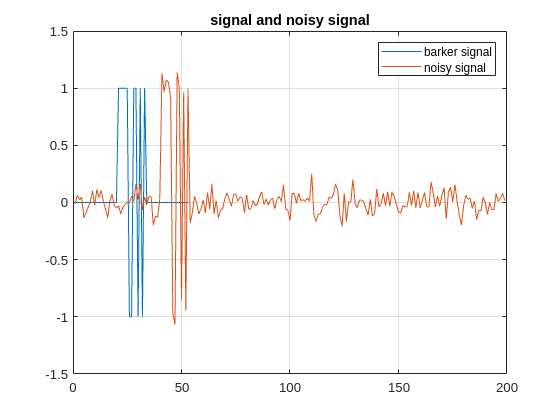


figure
plot(x_a)
hold on
plot(ya)
grid on
title('signal and noisy signal')
legend("barker signal","noisy signal")
hold off

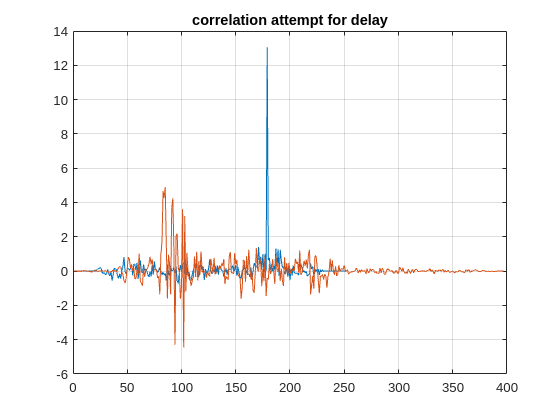


figure
rxy = conv(x_a,fliplr(ya));
rxy2 = conv(ya,ya);

plot (rxy)
hold on
title('correlation attempt for delay')
plot (rxy2)
grid on
hold off

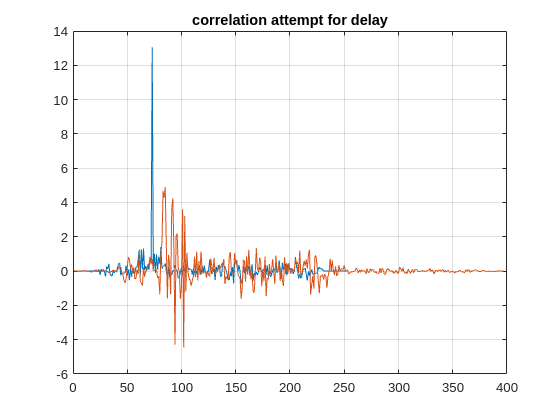

ryx = conv(ya,fliplr(x_a));
plot (ryx)
title('correlation attempt for delay')
hold on

ryx2 = conv(ya,ya);
plot (ryx2)
grid on
hold off

function a = convert(data)
g = 9.8; % as in m/s^2
a = -1.5*g + 3*g*(data/63);
end

function plot_avgs(x)
avg_vec = [1 1 1]./3;
conv_sig = conv(x,avg_vec);
plot(1:1:length(x),x,'b',2:1:(length(conv_sig)-1),conv_sig(2:end-1),'r');
title('combined signal and moving avg')
xlabel('samples n')
ylabel('value')
grid on
legend('original','avg')
end

% not actually the cross corr function since this isnt time rev. more like
% an auto corr
function crossCorr(x)
avg_vec = [1 1 1]./3;
conv_sig = conv(x,avg_vec);
hx = filter(avg_vec,1,x);
convX = conv(hx,x);
reg_range = (1:1:length(hx))';
new_range = -floor(length(convX)/2):1:floor(length(convX)/2);
figure()
plot(new_range,convX)
grid on
figure()
plot(reg_range,hx,'k*',1:1:length(x),x,'b:',1:1:length(conv_sig),conv_sig,'r')
title('Original signal with average and filter function')
legend("h_x","x","My_{avg}")
grid on
end

% not actually the cross corr function since this isnt time rev. more like
% an auto corr
function cross_corr(x,y,signals)
% figure()
% plot(x,'k*-')
% hold on
% plot(y,'b:')
% legend("x_{i}(n)","x_{j}(n)")
% title("signals x_{i}(n) and x_{j}(n)")
% grid on
% hold off
convXy = conv(x,flip(y));
figure()
new_range = -floor(length(convXy)/2):1:floor(length(convXy)/2);
plot(new_range,convXy,'r')
hold on
plot(new_range,conv(y,flip(x)),'b')
if x == y
hold on
plot(conv(x,y),'b')
title(sprintf("Correlation R_{%s} with autocorr",signals))
legend(sprintf("R_{%s}",signals), "autocorr")
grid on
hold off
else 
title(sprintf("Correlation R_{%s}",signals))
legend(sprintf("R_{%s}",signals),sprintf("R_{%s}",fliplr(signals)))
hold off
grid on
end
end

% difference eqs
function y = diffeq_1(x)
    y = zeros(size(x));
    y(1) = 0;
    for n = 2:length(x)
        y(n) = .8*(y(n-1)) + x(n);
    end
end

function y = diffeq_2(x)
    y = zeros(size(x));
    y(1) = 0;
    for n = 2:length(x)
        y(n) = (n/(n+1))*y(n-1) + (1/(n+1))*x(n);
    end
end

function y = diffeq_3(x)
    y = zeros(size(x));
    y(1) = 0;
    y(2) = y(1) + x(2);
    for n = 3:length(x)
        y(n) = y(n-1) - y(n-2) + x(n);
    end
end


function lti_test1(x,t,sig)
for i = 1:1:floor(length(x)/2)
    diff1= [diffeq1(x,t),x];
    plot(diff1)
    ylim([min(min(diff1(:,1)),min(diff1(:,2))) ...
        max(max(diff1(:,1)),max(diff1(:,2))) ]*1.2)
    title(sprintf('%s signal with diff eq function 1',sig))
    grid on
    hold on
    diff1= [diffeq1(x,i),x];
    plot(diff1(:,1),'--k')
    legend("y(n)","x(n)","y_{shifted}")
    hold off
    pause(.05)
end
end


function lti_test2(x,t,sig)
for i = 1:1:floor(length(x)/2)
    x_new = zeros(size(x));
    x_new(i:end) = x(i:end);
    diff2= [diffeq2(x_new,i),x_new];
    plot(diff2)
    ylim([min(min(diff2(:,1)),min(diff2(:,2))) ...
        max(max(diff2(:,1)),max(diff2(:,2))) ]*1.2)
    title(sprintf('%s signal with diff eq function 2',sig))
    grid on
    hold on
    diff2= [diffeq2(x_new,i),x_new];
    neweq = diff2(:,1);
    plot(neweq,'--k')
    legend("y(n)","x(n)","y_{shifted}")
    hold off
    pause(.05)
end
end


function lti_test3(x,t,sig)

diff3= [diffeq3(x,1),x];
lims = [min(min(diff3(:,1)),min(diff3(:,2))) ...
        max(max(diff3(:,1)),max(diff3(:,2))) ];

for i = 1:1:floor(length(x)/2)
    x_new = zeros(size(x));
    x_new(i:end) = x(i:end);
    diff3= [diffeq3(x_new,i),x_new];
    plot(diff3)
    ylim(lims*1.2)
    title(sprintf('%s signal with diff eq function 2',sig))
    grid on
    hold on
    diff3= [diffeq3(x_new,i),x_new];
    neweq = diff3(:,1);
    plot(neweq,'--k')
    legend("y(n)","x(n)","y_{shifted}")
    hold off
    pause(.05)
end
end
